Root of Equations

by: 13621060 フィズ

fsym = @f;

format long

xr = (fzero(fsym,[0 2]))

1.    Bisection Method

First ver.

clc, clf

% Bisection Method

% Initializing first two points
xlower = 0; 
xupper = 2;

% Initialize number of iteration
iter = 0;

% Intialize number of approximate error (Chapra page 132)
ea = abs(xupper - xlower) / (xupper + xlower) * 100;

% Declare stopping error
es = 1;

% Declare boolean
stop_iter = false;

% Loop until approximate error less than stopping error
while (~stop_iter)
    % Get the new xmid
    xmid = (xlower + xupper) / 2;
    
    % Increment the number of iteration
    iter = iter + 1;

    % Get the new approximate error
    ea = abs(xupper - xlower) / (xupper + xlower) * 100;
    
    % Get the new true erro
    et = abs(xmid - xr) / xr * 100;

    % Print the current information
    fprintf("xlower = %.6f\n", xlower);
    fprintf("xupper = %.6f\n", xupper);
    fprintf("xmid = %.6f\n", xmid);

    fprintf("f(xlower) = %.6f\n", f(xlower));
    fprintf("f(xupper) = %.6f\n", f(xupper));
    fprintf("f(xmid) = %.6f\n", f(xmid));

    fprintf("Approximate error = %.6f", ea);
    fprintf("True error = %.6f", et);

    fprintf("Iteration of %d\n", iter);

    xs = linspace(0,2,100);
    fs = f(xs);
    os = zeros(100);

    xes = [xlower, xmid, xupper];
    yes = f(xes);

    plot(xs,fs);
    hold on
    yline(0, 'black');
    hold off
    for x=xes
        hold on
        xline(x, 'r');
        hold off
    end
    hold on
    plot(xes,yes,"r*");
    hold off

    hold on
    grid on
    hold off

    xlabel("x");
    ylabel("y")

    xlim([0 2]);
    ylim([f(0) f(2)]);

    to_title = sprintf("Bisection Method, xr = %.10f", xmid);
    title(to_title);

    pause(0.1)

    % Check current error
    if (ea < es)
        % Toggle stop iteration
        stop_iter = true;
    else
        % If the sign of f(xmid) is different than f(xlower), then xmid become the
        % new xupper. Otherwise, otherwise.
        if (f(xmid) * f(xlower) < 0)
            xupper = xmid;
        else
            xlower = xmid;
        end
    end
end

2.    False Position Method

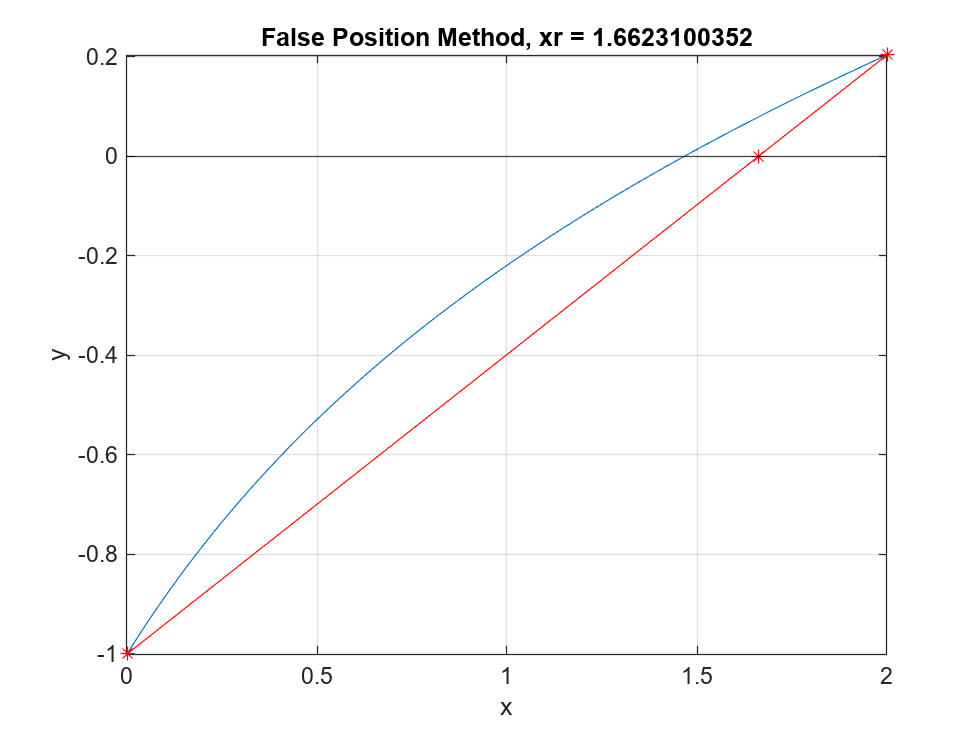

xlower = 0.000000


xupper = 2.000000


xroot = 1.662310


f(xlower) = -1.000000


f(xupper) = 0.203145


f(xroot) = 0.078923


Approximate error = 100.000000

True error = 13.283420

Iteration of 1


xlower = 0.000000


xupper = 1.662310


xroot = 1.540712


f(xlower) = -1.000000


f(xupper) = 0.078923


f(xroot) = 0.030400


Approximate error = 7.892304

True error = 4.996757

Iteration of 2


xlower = 0.000000


xupper = 1.540712


xroot = 1.495257


f(xlower) = -1.000000


f(xupper) = 0.030400


f(xroot) = 0.011660


Approximate error = 3.039951

True error = 1.899075

Iteration of 3


xlower = 0.000000


xupper = 1.495257


xroot = 1.478023


f(xlower) = -1.000000


f(xupper) = 0.011660


f(xroot) = 0.004465


Approximate error = 1.166032

True error = 0.724594

Iteration of 4


xlower = 0.000000


xupper = 1.478023


xroot = 1.471453


f(xlower) = -1.000000


f(xupper) = 0.004465


f(xroot) = 0.001708


Approximate error = 0.446476

True error = 0.276882

Iteration of 5


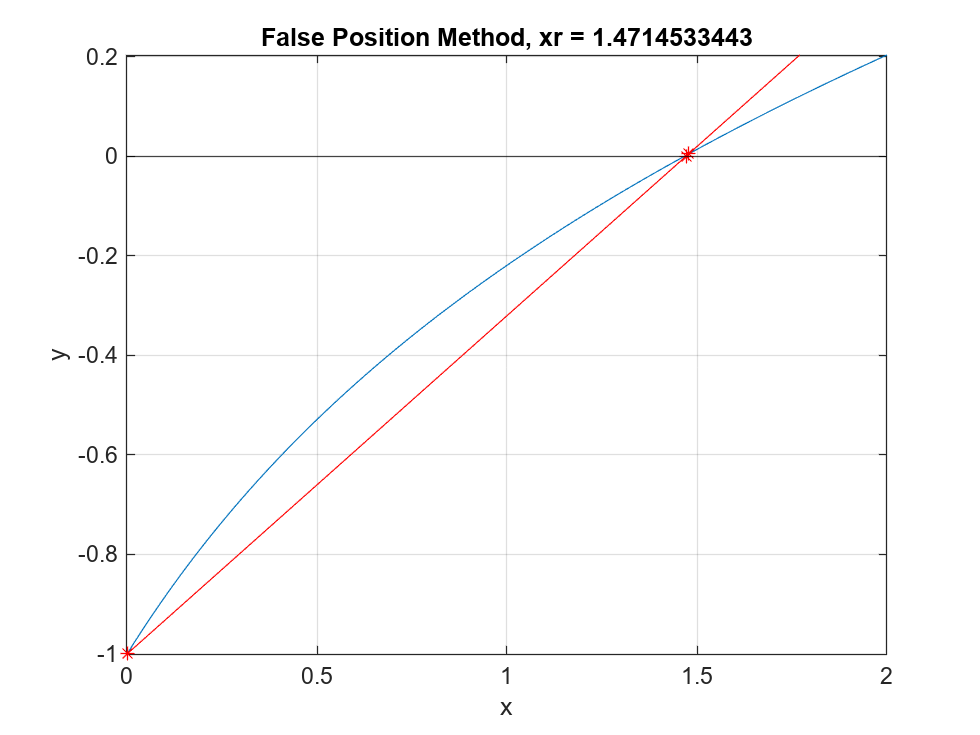

clc, clf

% Bisection Method

% Initializing first two points
xlower = 0; 
xupper = 2;

% Initialize number of iteration
iter = 0;

% Declare stopping error
es = 1;

% Declare boolean
stop_iter = false;

% Loop until approximate error less than stopping error
while (~stop_iter)
    % Get the previous root (except when first iteration
    if (iter >= 1)
        xroot_prev = xroot;
    end

    % Get the root of line connecting xlower and xupper (the false root)
    xroot = xlower - f(xlower) * (xupper - xlower) / (f(xupper) - f(xlower));

    % Increment the number of iteration
    iter = iter + 1;

    % Get the new approximate error
    if (iter > 1)
        ea = abs(xroot - xroot_prev) / xroot * 100;
    else
        ea = 100;
    end
    
    % Get the new true erro
    et = abs(xroot - xr) / xr * 100;

    % Print the current information
    fprintf("xlower = %.6f\n", xlower);
    fprintf("xupper = %.6f\n", xupper);
    fprintf("xroot = %.6f\n", xroot);

    fprintf("f(xlower) = %.6f\n", f(xlower));
    fprintf("f(xupper) = %.6f\n", f(xupper));
    fprintf("f(xroot) = %.6f\n", f(xroot));

    fprintf("Approximate error = %.6f", ea);
    fprintf("True error = %.6f", et);

    fprintf("Iteration of %d\n", iter);

    xs = linspace(0,2,100);
    fs = f(xs);
    os = zeros(100);

    xes = [xlower, xupper];
    yes = f(xes);

    plot(xs,fs);

    hold on
    yline(0, 'black');
    hold off

    hold on
    plot(xes,yes,"r*");
    hold off

    hold on
    plot(xroot,0,"r*")
    hold off

    hold on
    plot(xs, linef(xs, xlower, xupper), 'red');
    hold off

    hold on
    grid on
    hold off

    xlabel("x");
    ylabel("y")

    xlim([0 2]);
    ylim([f(0) f(2)]);

    to_title = sprintf("False Position Method, xr = %.10f", xroot);
    title(to_title);

    pause(2)

    % Check current error
    if (ea < es)
        % Toggle stop iteration
        stop_iter = true;
    else
        % If the sign of f(xroot) is different than f(xlower), then xroot become the
        % new xupper. Otherwise, otherwise.
        if (f(xroot) * f(xlower) < 0)
            xupper = xroot;
        else
            xlower = xroot;
        end
    end
end

Functions

function f = f(x)

g = 9.8;
v = 5;
L = 4;
t = 2.5;

f = (sqrt(2 .* g .* x) ./ v) .* tanh(sqrt(2 .* g .* x) .* t ./ (2 .* L)) - 1;

end

function y = linef(x, xlower, xupper)

y = f(xlower) + (x - xlower) * (f(xupper) - f(xlower)) / (xupper - xlower);

end